%johnny vastola Math 131
clc
clear

1.

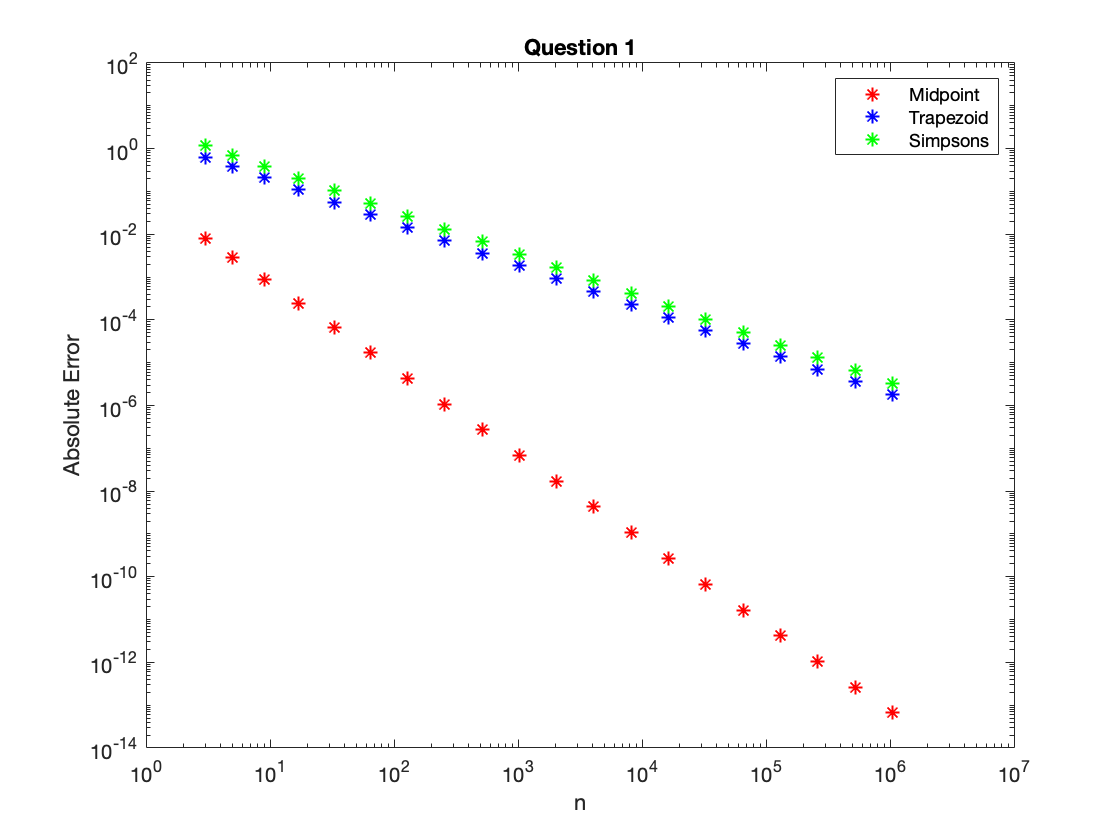

a=0;b=1;f= @(x) exp(x);n= @(k) 2.^k+1;
actual=exp(b)-1;
for i=1:20
    N(i)=n(i);
    emid(i)=abs(midpoint(f,a,b,n(i))-actual);
    etrap(i)=abs(traps(f,a,b,n(i))-actual);
    esimp(i)=abs(simpsons(f,a,b,n(i))-actual);
end
loglog(N,emid,'r*',N,etrap,'b*',N,esimp,'g*')
title('Question 1');xlabel('n');ylabel('Absolute Error');legend('Midpoint','Trapezoid','Simpsons');

2.

f= @(x) exp(x);a=0;b=1;
i_ex=exp(b)-exp(a);
i=integral(f,a,b);
err=abs(i_ex-i)

err = 4.4409e-16

3.

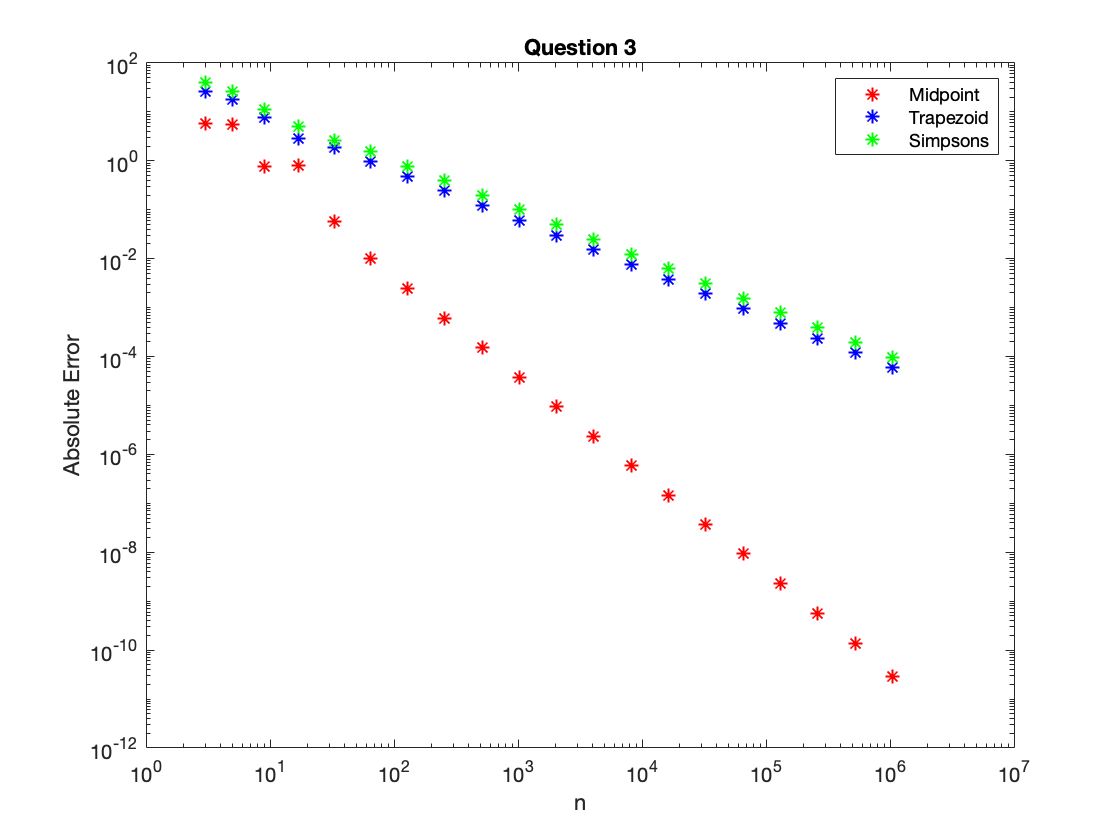

a=0; b=48; f= @(x) sqrt(1+(cos(x)).^2); n= @(k) 2.^k+1;
actual=integral(f,a,b);
for i=1:20
    N(i)=n(i);
    emid(i)=abs(midpoint(f,a,b,n(i))-actual);
    etrap(i)=abs(traps(f,a,b,n(i))-actual);
    esimp(i)=abs(simpsons(f,a,b,n(i))-actual);
end
loglog(N,emid,'r*',N,etrap,'b*',N,esimp,'g*')
title('Question 3');xlabel('n');ylabel('Absolute Error');legend('Midpoint','Trapezoid','Simpsons');

function r= midpoint(f,a,b,n)
    h = (b-a)/n;
    x = a+h/2:h:b-h/2;
    r = h * sum(f(x));
end
function r = traps(f,a,b,n)
    h = (b-a)/n;
    x = a+h/2:h:b-h/2;
    r = h*(sum(f(x)) - 0.5*f(a) - 0.5*f(b));
end
function r = simpsons(f,a,b,n)
    h = (b-a)/n;
    x = a:h:b;
    r = (h/3)*(f(x(1))+f(x(end))+2*sum(f(x(1:2:end)))+4*sum(f(x(2:2:end))));
end

